# TA2: PID

## ANÁLISIS DE LA APROXIMACIÓN FOPDT FINAL (PRBS)

Basado en el modelo obtenido en el ensayo de PRBS y del escalón, se obtuvo:


$$\begin{array}{l}
G_{\textrm{FOPDT}} =\frac{K_p e^{-\textrm{Ls}} }{1+\textrm{Ts}}=\frac{\left(0\ldotp 98257\right)e^{-\left(0\ldotp 34639\right)s} }{1+\left(0\ldotp 50484\right)s}\\
T=0\ldotp 50484\\
L=0\ldotp 34639\\
K_{p\;} =0\ldotp 98257
\end{array}$$


% Defino el modelo FOPDT y los parámetros del PID
s = tf('s');

T =  0.50484;
L  = 0.34639;
K_p = 0.98257;

G_sin_retardo = (K_p)/(1+s*T);
G_fopdt = G_sin_retardo; 
G_fopdt.InputDelay = L; 
tf_fopdt_prbs_medida = G_fopdt;
tf_fopdt_ideal = G_fopdt

tf_fopdt_ideal =
 
                     0.9826
  exp(-0.346*s) * ------------
                  0.5048 s + 1
 
Continuous-time transfer function.



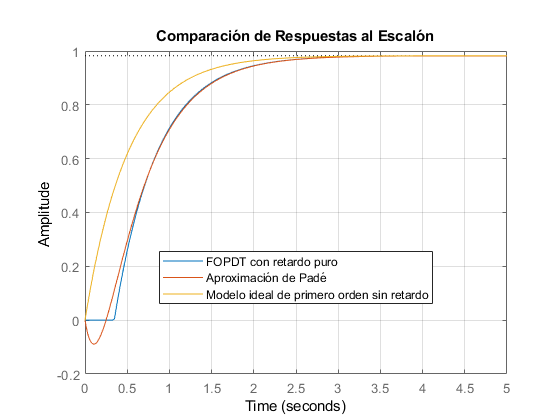

G_aprox = G_sin_retardo*(1-(s*L/2))/(1+(s*L/2));  %  Aproximado por Padé

% grafico

figure;
h = stepplot(G_fopdt, G_aprox, G_sin_retardo);
grid on;
title("Comparación de Respuestas al Escalón");

legend( ...
    'FOPDT con retardo puro', ...
    'Aproximación de Padé', ...
    'Modelo ideal de primero orden sin retardo', ...
    'Location','best' );

## DISEÑO DEL PID (asignación de polos)

Basado el el modelo aproximado de primer orden, se diseña el PID para una respuesta crítica sin sobrepaso. Se elije asignación de polos por esta razón.


$$G_{\textrm{aprox}} \;\;=\;\frac{\left(0\ldotp 98662\right)\left(1-\frac{\left(\textrm{s0}\ldotp 15\right)}{2}\right)}{\left(1+\left(0\ldotp 75618\right)s\right)\left(1+\frac{s\left(0\ldotp 15\right)}{2}\right)}$$



$$PID_{SP}(s) = 
\frac{k_c (1 + T_I s)(1 + T_D s)}
{T_I s (1 + \alpha T_D s)},$$


% Defino parametros del modelo
s = tf('s');

T =  0.50484;
L  = 0.34639;
K_p = 0.98257;

% Defino parametros del PID

T_D = 0.5*L;
T_I = T;
alfa = 0.6; %  0.6 final
T_0 = (sqrt(alfa*alfa + alfa) + alfa)*L/2

T_0 = 0.2736

k_c  = 2*T/(K_p*(L  + 4*T_0));

% Calculo transferencias del PID
PID = (k_c*(1+T_I*s)*(1+T_D*s))/(T_I*s*(1+alfa*T_D*s))

PID =
 
                             
  0.06236 s^2 + 0.4836 s     
                             
                     + 0.7132
                             
  ---------------------------
                          
    0.05246 s^2 + 0.5048 s
                          
 
Continuous-time transfer function.



## Plantas a ensayar:


% Planta ideal de 6 polos
tf_6polos_ideal = 1/(s*0.1 + 1)^6;

% Planta de 6 polos modelada con la prbs
tf_6polos_prbs_medida = tf([5.671618964260604e+05] , [1,58.284099674190490,1.284445491209403e+03,1.622971004687713e+04,1.087898782652298e+05,3.983829952470905e+05,5.775054615523315e+05]);

% Planta de orden 1 modelada con la prbs, retardo real
G_sin_retardo = (K_p)/(1+s*T);
G_fopdt = G_sin_retardo; 
G_fopdt.InputDelay = L; 

% Planta de orden 1 con pade
G_fopdt_pade = G_sin_retardo * (1 - (L/2)*s) / (1 + (L/2)*s);


## Transferencias LC

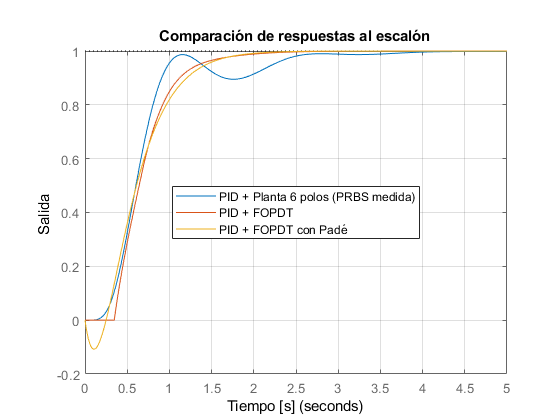



T_PID_6polos = feedback(tf_6polos_prbs_medida*PID, 1);
T_PID_fopdt = feedback(G_fopdt*PID, 1);
T_PID_pade = feedback(G_fopdt_pade*PID, 1);

% Gráfico
figure;
h = stepplot(T_PID_6polos, T_PID_fopdt, T_PID_pade);
grid on;

title('Comparación de respuestas al escalón');
xlabel('Tiempo [s]');
ylabel('Salida');

legend( ...
    'PID + Planta 6 polos (PRBS medida)', ...
    'PID + FOPDT', ...
    'PID + FOPDT con Padé', ...
    'Location','Best' ...
);

## Test distintos valores de alfa

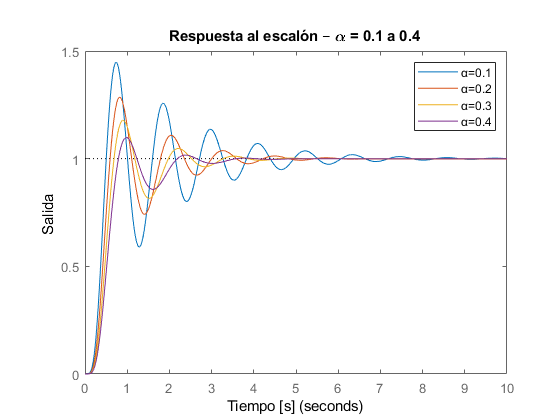

% Defino variable de Laplace
s = tf('s');

% Parametros del modelo
T   = 0.50484;
L   = 0.34639;
K_p = 0.98257;

% Parametros fijos del PID
T_D = 0.5*L;
T_I = T;

%% ===== Plot 1: alfa de 0.1 a 0.4 =====
alfa_vec_1 = 0.1:0.1:0.4;

figure
hold on
grid on

for alfa = alfa_vec_1

    T_0 = (sqrt(alfa^2 + alfa) + alfa)*L/2;
    k_c = 2*T/(K_p*(L + 4*T_0));

    PID = (k_c*(1 + T_I*s)*(1 + T_D*s)) / ...
          (T_I*s*(1 + alfa*T_D*s));

    T_PID_6polos = feedback(tf_6polos_prbs_medida*PID, 1);

    step(T_PID_6polos)

end

title('Respuesta al escalón – \alpha = 0.1 a 0.4')
xlabel('Tiempo [s]')
ylabel('Salida')
legend('α=0.1','α=0.2','α=0.3','α=0.4')

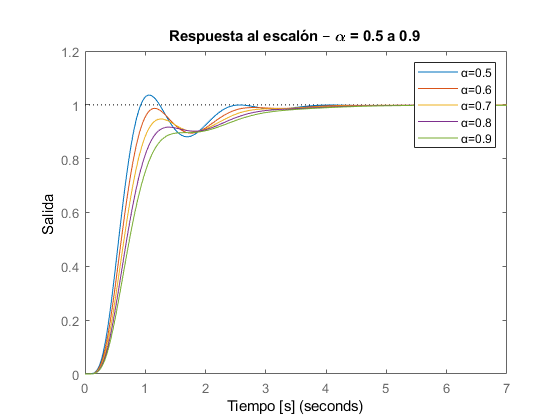



%% ===== Plot 2: alfa de 0.5 a 0.9 =====
alfa_vec_2 = 0.5:0.1:0.9;

figure
hold on
grid on

for alfa = alfa_vec_2

    T_0 = (sqrt(alfa^2 + alfa) + alfa)*L/2;
    k_c = 2*T/(K_p*(L + 4*T_0));

    PID = (k_c*(1 + T_I*s)*(1 + T_D*s)) / ...
          (T_I*s*(1 + alfa*T_D*s));

    T_PID_6polos = feedback(tf_6polos_prbs_medida*PID, 1);

    step(T_PID_6polos)

end

title('Respuesta al escalón – \alpha = 0.5 a 0.9')
xlabel('Tiempo [s]')
ylabel('Salida')
legend('α=0.5','α=0.6','α=0.7','α=0.8','α=0.9')

## Transferencias perturbación en la accion de control

SG_6polos = tf_6polos_prbs_medida/(1+tf_6polos_prbs_medida*PID);
SG_fopdt  = G_fopdt/(1+G_fopdt*PID);
SG_fopdt.InputDelay = L; 
SG_pade   = G_fopdt_pade/(1+G_fopdt_pade*PID);

## Discretizacion de la planta, cálculo de los coeficientes

Como es un controlador de 2 ceros y 2 polos:


$$\frac{U\left(z\right)}{E\left(z\right)}=\frac{a_0 +a_1 z^{-1} +a_2 z^{-2} }{{1-\;b}_1 z^{-1} -b_2 z^{-2} }$$


La ecuación en diferencias tiene que tener la siguiente forma:


$$u\left\lbrack k\right\rbrack =a_0 e\left\lbrack k\right\rbrack +a_1 e\left\lbrack k-1\right\rbrack +a_2 e\left\lbrack k-2\right\rbrack +b_1 u\left\lbrack k-1\right\rbrack +b_2 e\left\lbrack k-2\right\rbrack$$


% Defino parametros del modelo
s = tf('s');

T =  0.50484;
L  = 0.34639;
K_p = 0.98257;

Tm = 0.030;

% Defino parametros del PID

T_D = 0.5*L;
T_I = T;
alfa = 0.6;
T_0 = (sqrt(alfa*alfa + alfa) + alfa)*L/2;
k_c  = 2*T/(K_p*(L  + 4*T_0));

PID = (k_c*(1+T_I*s)*(1+T_D*s))/(T_I*s*(1+alfa*T_D*s));

PIDz = c2d(PID, Tm, 'zoh');
[x, y] = tfdata(PIDz, 'v'); % Coef multiplicados por 1000:
coeficientes_a0_a1_a2 = x*1000

coeficientes_a0_a1_a2 = 	1.0e+03 *

    1.1886   -2.1315    0.9535


coeficientes_b0_b1_b2 = -y*1000

coeficientes_b0_b1_b2 = 	1.0e+03 *

   -1.0000    1.7492   -0.7492


## Robustez para la familia de modelos

%--------------------------------------------
% Familia de modelos de la planta G

t1 = ureal('t1', 0.1, 'Range', [0.08 0.12]);
t2 = ureal('t2', 0.1, 'Range', [0.08 0.12]);
t3 = ureal('t3', 0.1, 'Range', [0.08 0.12]);
t4 = ureal('t4', 0.1, 'Range', [0.08 0.12]);
t5 = ureal('t5', 0.1, 'Range', [0.08 0.12]);
t6 = ureal('t6', 0.1, 'Range', [0.08 0.12]);

s = tf('s');

G = 1 / ((s*t1+1)*(s*t2+1)*(s*t3+1)*(s*t4+1)*(s*t5+1)*(s*t6+1))

G =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 13 states.
  The model uncertainty consists of the following blocks:
    t1: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t2: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t3: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t4: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t5: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t6: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences

Type "G.NominalValue" to see the nominal value, "get(G)" to see all properties, and "G.Uncertainty" to interact with the uncertain elements.




%---------------------------------------------
% Modelo de la planta Fopdt

T =  0.50484;
L  = 0.34639;
K_p = 0.98257;

G_fopdt = (K_p)/(1+s*T);

%----------------------------------------------
% PID

T_D = 0.5*L;
T_I = T;
alfa = 0.6;
T_0 = (sqrt(alfa*alfa + alfa) + alfa)*L/2;

T_0 = 0.2736

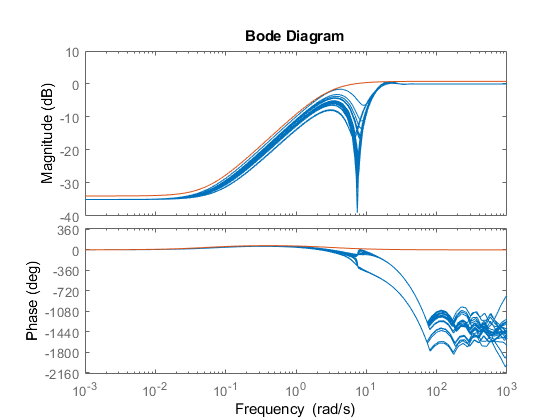

k_c  = 2*T/(K_p*(L  + 4*T_0));

PID = (k_c*(1+T_I*s)*(1+T_D*s))/(T_I*s*(1+alfa*T_D*s));

%----------------------------------------------
% Modelo de la planta de 6 polos
xg = [5.671618964260603e+05];
yg = 1.0e+05 *[0.000010000000000 0.000582840996742 0.012844454912094 0.162297100468771 1.087898782652298 3.983829952470905 5.775054615523315];

G_posta = tf(xg, yg);

%----------------------------------------------
% funciones de tranferencia

Tfopdt = feedback(G_fopdt*PID, 1);

Tposta = feedback(G_posta*PID, 1);

%----------------------------------------------
% Robustez para modelo nominal fopdt

w = 1 + s - s;
w.InputDelay = L; 
w = G/G_fopdt - w;

W_foppdt = 1.097*(s + 0.055 )/(s + 3);

bode(w, W_foppdt)

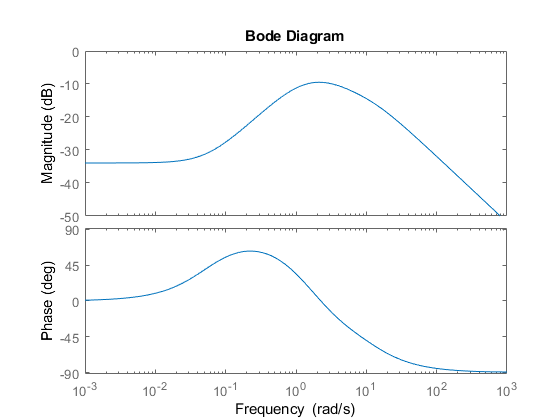

bode(Tfopdt*W_foppdt)

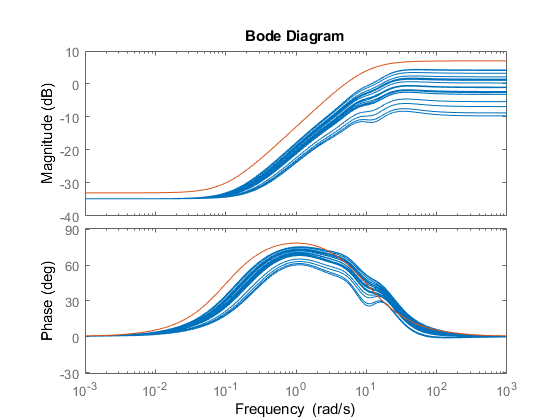


%----------------------------------------------
% Robustes para modelo nominal de 6 polos


ww = G/G_posta -1;

W_posta = 2.24*(s + 0.1 )/(s + 10);

bode(ww, W_posta)

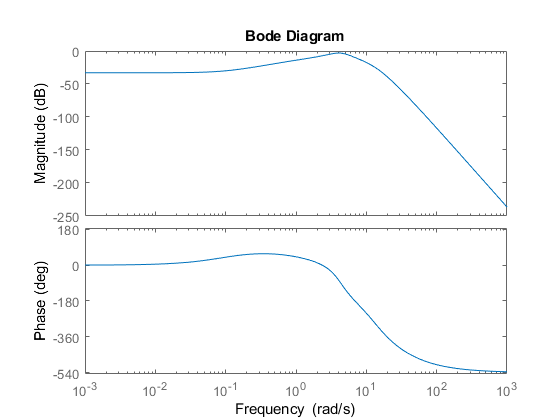

bode(Tposta*W_posta)


%----------------------------------------------


## COMPARACIÓN

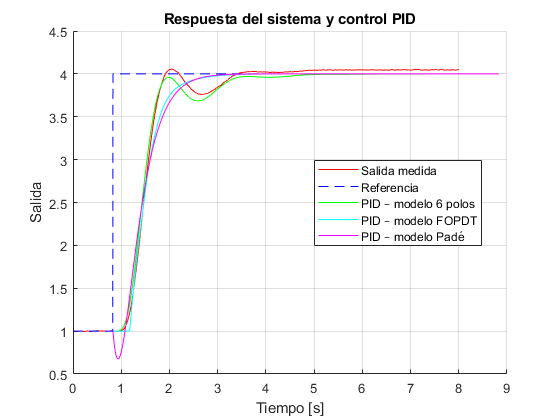

% cambio de referencia
datos_respuesta_cambio_referencia = readtable('r.CSV');

referencia = datos_respuesta_cambio_referencia.Var1;
referencia(referencia < 2500) = 1;
referencia(referencia >= 2500) = 4;

datos = datos_respuesta_cambio_referencia.Var2;
datos = (datos -mean(datos(1:3000))) / 1000;
% --- Filtro pasabajos ---
fs = 4000;
fc = 10;
[b_med, a_med] = butter(4, fc/(fs/2));

datos = filter(b_med, a_med, datos)+1;

tiempo = (0:0.00025:0.00025*(size(datos)-1));

y_PID_6polos = 3 * step(T_PID_6polos,tiempo) + 1;
y_PID_fopdt  = 3 * step(T_PID_fopdt, tiempo) + 1;
y_PID_pade   = 3 * step(T_PID_pade,  tiempo) + 1;


figure; grid on; hold on;

plot(tiempo, datos, 'r');
plot(tiempo, referencia, 'b--');
plot(tiempo + tiempo(3315), y_PID_6polos, 'g');
plot(tiempo + tiempo(3315), y_PID_fopdt, 'c');
plot(tiempo + tiempo(3315), y_PID_pade,  'm');

xlabel('Tiempo [s]');
ylabel('Salida');
title('Respuesta del sistema y control PID');

legend( ...
    'Salida medida', ...
    'Referencia', ...
    'PID – modelo 6 polos', ...
    'PID – modelo FOPDT', ...
    'PID – modelo Padé', ...
    'Location','best');

hold off;


mean(datos(24000:end))

ans = 4.0466

mean(datos(500:3500))

ans = 1.0004


3.364-0.8285

ans = 2.5355

1.142-0.8285

ans = 0.3135

3.364-1.169

ans = 2.1950

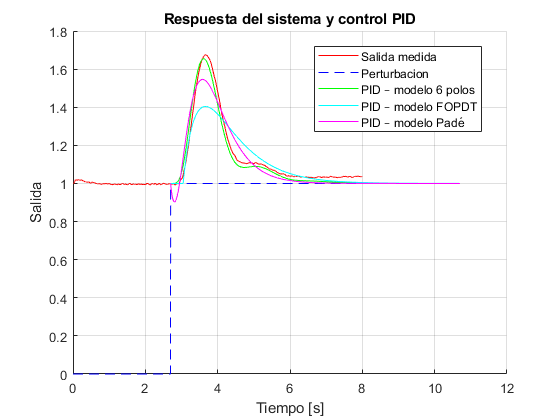


% respuesta a la perturbaciones
datos_respuesta_perturbaciones = readtable('p.CSV');


perturbacion = datos_respuesta_perturbaciones.Var1;
perturbacion(perturbacion < 2500) = 0;
perturbacion(perturbacion >= 2500) = 1;

datos_p = datos_respuesta_perturbaciones.Var2;
datos_p = (datos_p - mean(datos_p(1:10000))) / 1000;
% --- Filtro pasabajos ---
fs = 4000;
fc = 10;
[b_med, a_med] = butter(4, fc/(fs/2));

datos_p = filter(b_med, a_med, datos_p) + 1;

tiempo_p = (0:0.00025:0.00025*(size(datos_p)-1));

y_SG_6polos = step(SG_6polos,tiempo_p) + 1;
y_SG_fopdt  = step(SG_fopdt, tiempo_p) + 1;
y_SG_pade   = step(SG_pade,  tiempo_p) + 1;

figure; grid on; hold on;

plot(tiempo_p, datos_p, 'r');
plot(tiempo_p, perturbacion, 'b--');
plot(tiempo_p + tiempo_p(10796), y_SG_6polos, 'g');
plot(tiempo_p + tiempo_p(10796), y_SG_fopdt, 'c');
plot(tiempo_p + tiempo_p(10796), y_SG_pade,  'm');

xlabel('Tiempo [s]');
ylabel('Salida');
title('Respuesta del sistema y control PID');

legend( ...
    'Salida medida', ...
    'Perturbacion', ...
    'PID – modelo 6 polos', ...
    'PID – modelo FOPDT', ...
    'PID – modelo Padé', ...
    'Location','best');

hold off;


mean(datos_p(24000:end))

ans = 1.0342

mean(datos_p(4000:10000)) + 50

ans = 50.9962


3.014 - 2.699

ans = 0.3150

5.85 - 3.014

ans = 2.8360

## Simulacion/real escalon

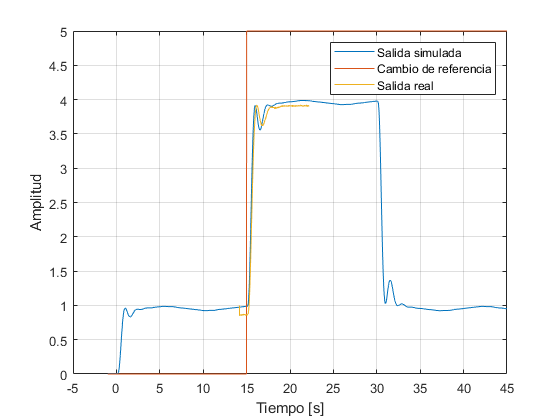

% Datos simulados
datos_sim_ref = readmatrix('cambio_de_referencia_simulacion.DAT');

tiempo_sim = datos_sim_ref(:,1);
salida_sim = datos_sim_ref(:,2);
escalon_sim = datos_sim_ref(:,3);

% Datos del osciloscopio
datos_respuesta_cambio_referencia = readtable('r.CSV');

referencia = datos_respuesta_cambio_referencia.Var1;
datos = datos_respuesta_cambio_referencia.Var2;
datos = datos -1000;
% --- Filtro pasabajos ---
fs = 4000;
fc = 50;
[b_med, a_med] = butter(4, fc/(fs/2));

datos = filter(b_med, a_med, datos)+1000;

tiempo = (0:0.00025:0.00025*(size(datos)-1));

% desplazar en el tiempo para sincronizar los escalones
i=1;
while referencia(i)<3000
    nr = i;
    i = i + 1;
end

i=1;
while escalon_sim(i)<3
    ne = i;
    i = i + 1;
end

tiempo = tiempo + tiempo_sim(ne) -tiempo(nr);

% grafico
plot(tiempo_sim, salida_sim, ...
     tiempo_sim, escalon_sim, ...
     tiempo, datos/1000);

xlabel('Tiempo [s]');
ylabel('Amplitud');

legend('Salida simulada', ...
       'Cambio de referencia', ...
       'Salida real');
grid on;

## Simulacion/real perturbacion

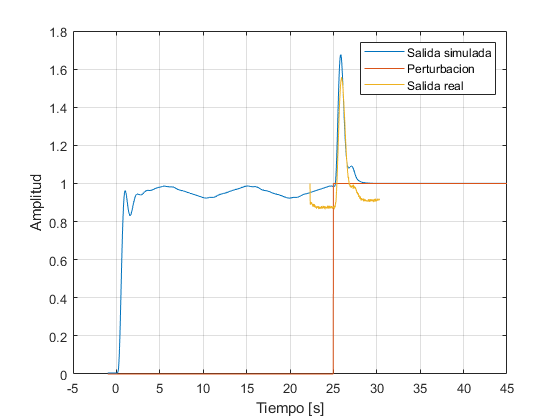

% Datos simulados
datos_sim_per = readmatrix('perturbacion_simulacion.DAT');

tiempo_p_sim = datos_sim_per(:,1);
salida_p_sim = datos_sim_per(:,2);
perturbacion_sim = datos_sim_per(:,3);

% Datos del osciloscopio
datos_respuesta_perturbaciones = readtable('p.CSV');


perturbacion = datos_respuesta_perturbaciones.Var1;
datos_p = datos_respuesta_perturbaciones.Var2;
datos_p = datos_p -1000;
% --- Filtro pasabajos ---
fs = 4000;
fc = 30;
[b_med, a_med] = butter(4, fc/(fs/2));

datos_p = filter(b_med, a_med, datos_p)+1000;

tiempo_p = (0:0.00025:0.00025*(size(datos_p)-1));


% desplazar en el tiempo para sincronizar los escalones
i=1;
while perturbacion(i)<3000
    nr = i;
    i = i + 1;
end

i=1;
while perturbacion_sim(i)<3
    ne = i;
    i = i + 1;
end

tiempo_p = tiempo_p + tiempo_p_sim(ne) -tiempo_p(nr);

% grafico
plot(tiempo_p_sim, salida_p_sim, ...
     tiempo_p_sim, perturbacion_sim/5, ...
     tiempo_p, datos_p/1000);

xlabel('Tiempo [s]');
ylabel('Amplitud');

legend('Salida simulada', ...
       'Perturbacion', ...
       'Salida real');
grid on;




17.09 - 15

ans = 2.0900

17.09 - 15.26

ans = 1.8300

15.26 - 15

ans = 0.2600



27.49 -25.3

ans = 2.1900

25.3 - 25

ans = 0.3000